clear
rosshutdown

OwnComputerIP = 'ROS_IP';'192.168.7.24';
OwnComputerHost = '192.168.7.24';
RobotIP = 'http://192.168.7.33:11311';

rosshutdown
setenv('ROS_MASTER_URI',RobotIP)
setenv(OwnComputerIP)
rosinit(RobotIP,'NodeHost', OwnComputerHost);

% Create Occupancy Map
image = imread('C:\Uni\6_semester\ROB2\Gruppe7Ros\Final Project\shannon.png');

% Convert to grayscale and black and white image
grayimage = rgb2gray(image);
bwimage = grayimage < 220;

grid = robotics.BinaryOccupancyGrid(bwimage);
map = flipud(grid.getOccupancy());

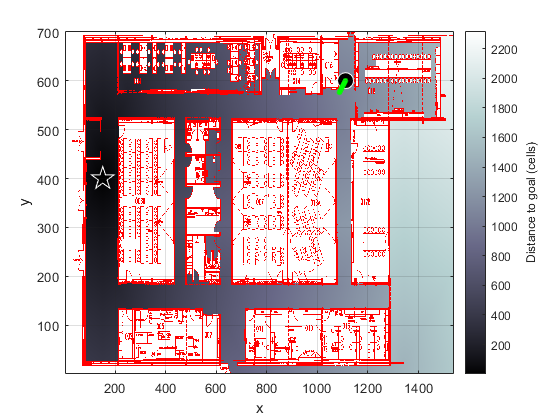

% Find shortest path
robotInitialLocation = [1111; 600]; 
robotGoal = [150; 400]; 

dx = DXform(map);
dx.plan(robotGoal);
path = dx.query(robotInitialLocation, 'animate'); 

path = [0 0; 0 0.5; 0 1; 0 1.5; 0 2; 0.5 2; 1 2; 1.5 2; 2 2; 2.5 2; 3 2; 3 1.5; 3 1; 3 0.5; 3 0; 2.5 0;2 0;1.5 0;1 0; 0.5 0];
%robotInitialLocation = path(1,:);
%robotGoal = path(end,:);
initialOrientation = 90;
robotCurrentPose = [robotInitialLocation, initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 0.5, "VehicleInputs", "VehicleSpeedHeadingRate");

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 6])
ylim([0 3])

controller = controllerPurePursuit;

controller.Waypoints = path;

controller.DesiredLinearVelocity = 0.6;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.5;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;

robotRealLife = rospublisher('/mobile_base/commands/velocity');
odom = rossubscriber('/odom');

resetPos = rospublisher('/mobile_base/commands/reset_odometry');
velmsg = rosmessage(robotRealLife);
resetmsg = rosmessage(resetPos);
send(resetPos, resetmsg);

% Drive until reaching goal destination
while( distanceToGoal > goalRadius )
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
 
    velmsg.Angular.Z = omega;
    velmsg.Linear.X = v;
    %velmsg.Angular.Y = vel(2);
    send(robotRealLife,velmsg);
   
    % Trying to use the robot position
    %odomdata = receive(odom);
    %pose = odomdata.Pose.Pose;
    %x = pose.Position.X;
    %y = pose.Position.Y;
    %z = pose.Position.Z;
    
    %robotCurrentPose = [x, y, z];
    
    disp(robotCurrentPose)
    % Update the current pose
    robotCurrentPose = robotCurrentPose +vel*sampleTime
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
   
   %controller.release();
    waitfor(vizRate);
end

velocity = 0;
velmsg.Linear.X = velocity;
send(robotRealLife, velmsg)